# `Exercise 1)`

# `Task A)`

clear;
% given data
u=[1 2 3 4 5]';
y=[6 7 8 9 -1]';

% you can test the following calls. After the call the correct answer is
% given

uy2phi([y u],[1 1 0])

ans =      7     6     2
     8     7     3
     9     8     4
    -1     9     5


%      7     6     2
%      8     7     3
%      9     8     4
%     -1     9     5

uy2phi([y u],[1 1 1])

ans =      7     6     1
     8     7     2
     9     8     3
    -1     9     4


%      7     6     1
%      8     7     2
%      9     8     3
%     -1     9     4

uy2phi([y u],[1 1 2])

ans =      8     7     1
     9     8     2
    -1     9     3


%      8     7     1
%      9     8     2
%     -1     9     3

uy2phi([y u],[1 2 2])

ans =      9     8     2     1
    -1     9     3     2


%      9     8     2     1
%     -1     9     3     2

uy2phi([y u],[3 2 2])

ans =      9     8     7     6     2     1
    -1     9     8     7     3     2


%      9     8     7     6     2     1
%     -1     9     8     7     3     2

# `Task B)`

# `Task C)`

clear;
% given data
u=[1 -1 2 -1 3 0 1]';
y=[2 -2 -3 -4 -2 0 1]';

% Your estimate should be
model=arxfit([y u],[2 1 2]);

model.theta

ans =     1.1573
   -0.5004
    0.2366



%     1.1573
%    -0.5004
%     0.2366


idpredict(model,[y u],1)

ans =          0
    2.3146
   -3.0789
   -2.7077
   -2.6550
   -0.5496
    1.7105



%          0
%     2.3146
%    -3.0789
%    -2.7077
%    -2.6550
%    -0.5496
%     1.7105


idpredict(model,[y u],3)

ans =          0
         0
    0.2366
    3.1374
   -6.7238
    0.9484
   -0.9916



%          0
%          0
%     0.2366
%     0.8209
%    -1.2256
%    -0.2234
%     0.5249


ysim=idsimulate(model,u)

ysim =          0
         0
    0.2366
    0.0372
    0.3978
    0.2052
    0.7481



%          0
%          0
%     0.2366
%     0.0372
%     0.3978
%     0.2052
%     0.7481

# `Task D)`

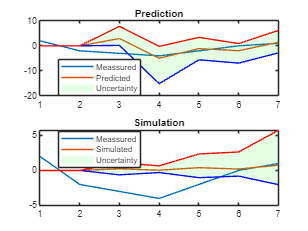

% The following two calls give the figures displayed in the project
% instructions

idcompare(model,[y u],2)

idcompare(model,[y u],Inf)

Out of memory. The likely cause is an infinite recursion within the program.

Error in idpredict (line 4)
        phi = uy2phi([zeros(zero, 2); z], [model.na, model.nb, model.nk]); % Generate regressor

# `Exercise 2)`

clear;
% True system parameters
B_true = [0.5, 0.3];  % True B coefficients
A_true = [1, -1.2, 0.36];  % True A coefficients
nk = 1;  % Input delay

% Generate input data
N = 5000;  % High number of data points to test convergence
u = randn(N, 1);  % Random input signal

% Generate noise-free system output using the true parameters
y_true = filter([0, B_true], A_true, u);  % Incorporate nk delay

% Add white noise to the output
noise_variance = 5;
noise = sqrt(noise_variance) * randn(N, 1);
y_noisy = y_true + noise;

% Parameters for OE and ARX model fitting
nb = length(B_true);  % Number of B coefficients
nf = length(A_true) - 1;  % Number of F coefficients in OE model, which is length(A_true) - 1

% Fit an OE model using the oefit function
oe_params = [nb, nf, nk];
oe_model = oefit([y_noisy, u], oe_params);

% Fit an ARX model directly using the same noisy data
arx_params = [nf, nb, nk];  % ARX model parameters need adjustment for comparison
arx_model = arxfit([y_noisy, u], arx_params);

% Display the estimated parameters
disp('True B coefficients:');

True B coefficients:


disp(B_true);

    0.5000    0.3000




disp('Estimated B coefficients from OE model:');

Estimated B coefficients from OE model:


disp(oe_model.B);

    1.0877
   -0.2536




disp('Estimated B coefficients from ARX model:');

Estimated B coefficients from ARX model:


disp(arx_model.B);

    0.5428
    0.7903




% Evaluation: Compute the Mean Squared Error of the estimates
mse_oe = mean((B_true - oe_model.B).^2);
mse_arx = mean((B_true - arx_model.B).^2);

disp(['MSE for OE Model: ', num2str(mse_oe)]);

MSE for OE Model: 0.45667     0.46347


disp(['MSE for ARX Model: ', num2str(mse_arx)]);

MSE for ARX Model: 0.043059     0.14968


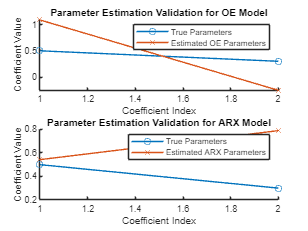


% Additional validation by plotting the estimates and true parameters
figure;
subplot(2,1,1);
hold on;
plot(B_true, 'o-', 'DisplayName', 'True Parameters');
plot(oe_model.B, 'x-', 'DisplayName', 'Estimated OE Parameters');
legend;
title('Parameter Estimation Validation for OE Model');
xlabel('Coefficient Index');
ylabel('Coefficient Value');

subplot(2,1,2);
hold on;
plot(B_true, 'o-', 'DisplayName', 'True Parameters');
plot(arx_model.B, 'x-', 'DisplayName', 'Estimated ARX Parameters');
legend;
title('Parameter Estimation Validation for ARX Model');
xlabel('Coefficient Index');
ylabel('Coefficient Value');

# `Exercise 3)`